Demo code for Figure 3 of Idesis (2022) - Introducing structural disconnection masks in whole-brain models. A mechanistic explanation of stroke patients effective connectivity

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load Time series, Structural connectivity and effective connectivity

load Data_Hopf_model.mat %Demo data (Only 2 subjects per group)
load('Networks_Demo.mat')
load('Network_communication.mat')
Nodes=235;
Isubdiag = find(tril(ones(Nodes),-1)); %Upper triangle indexes needed later for PCA analysis

Create fake data for lesion volume and nihss

lesion_volume=rand(1,size(EC_patients,3));
nihss=rand(1,size(EC_patients,3));

PCA of effective connectivity matrices

matrix_for_pca_patients = zeros(size(EC_patients,3),length(Isubdiag)); %Preallocate variable
for subj = 1:size(EC_patients,3)
    matrix_to_take_upper_part=EC_patients(:,:,subj); %Locate data in a temporary matrix to apply z-scoring
    matrix_for_pca_patients(subj,:) = matrix_to_take_upper_part(Isubdiag); %vector of containing the upper triangle of each patient
end

Spatial PCA for patients (This is for 1 time, replicate previous steps for other time points)

X= matrix_for_pca_patients'; %Define matrix to be used (subjects x upper-triangle data points)
X(isinf(X))=0; X(isnan(X))=0; %Check that there are not infinite or nan values
[~,score,~,~,explained] = pca(X); %Calculate PCA
explained_patients=explained(:) %Show how much variance is explained in each of the top 3 Components

explained_patients =    92.7694
    7.2306


pc_patients_EC=score(1,:); %Store the first PC for each patient

Regression PCA - Lesion volume and nihss

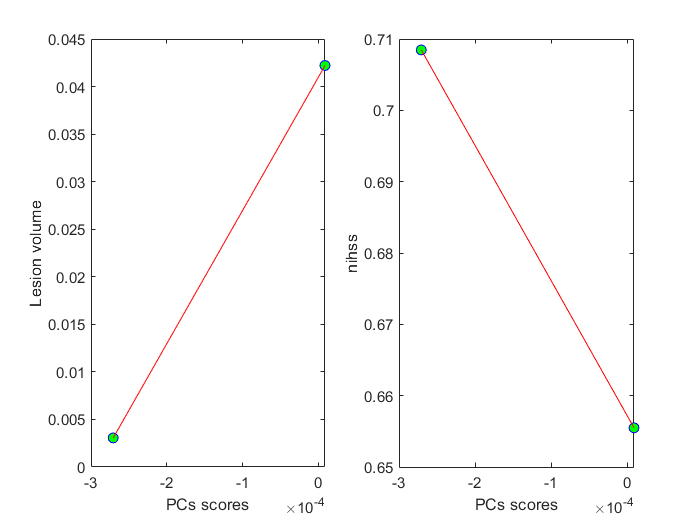

figure()
subplot(121)
mdlr = fitlm(pc_patients_EC,lesion_volume);
regr_plot=plot(mdlr);
legend('off')
xlabel('PCs scores');
ylabel('Lesion volume')
set(regr_plot(1),'Marker','o')
set(regr_plot(1),'MarkerFaceColor','g')
title('')

subplot(122)
mdlr = fitlm(pc_patients_EC,nihss);
regr_plot=plot(mdlr);
legend('off')
xlabel('PCs scores');
ylabel('nihss')
set(regr_plot(1),'Marker','o')
set(regr_plot(1),'MarkerFaceColor','g')
title('')

Create fake data for FC PCs, dynamic PCs and Behavior value

pc_patients_FC=rand(1,size(EC_patients,3));
pc_patients_dyn=rand(3,size(EC_patients,3)); %3 dynamical components (For more information, check Favaretto et al 2022)
Behavior=randi([1 8],1,size(EC_patients,3));

Regression PCs on Behavior

Elements in demo were repeated 10 times and shuffled to avoid overfitting of the regression (If there are more subjects, this step is not needed)

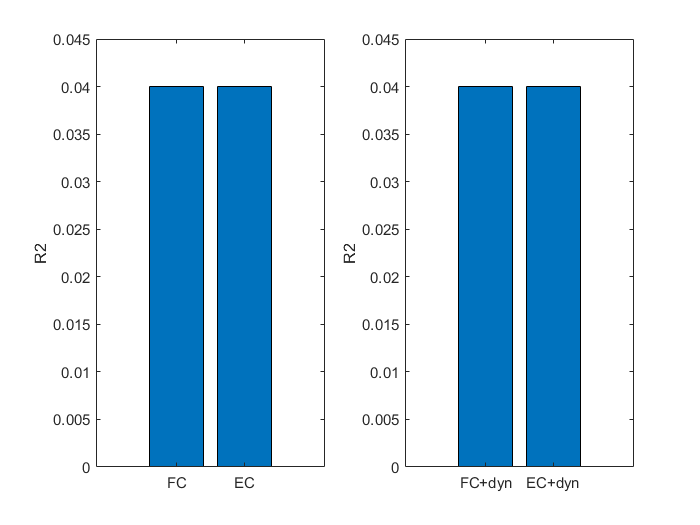

temp_EC=repelem(pc_patients_EC,10);idx_shuff=randperm(length(temp_EC)); % Comment the repetion if there are more than 2 subjects)
mdlr = fitlm(temp_EC(idx_shuff),repelem(Behavior,10));
r2_EC = mdlr.Rsquared.Ordinary;

temp_FC=repelem(pc_patients_FC,10);idx_shuff=randperm(length(temp_FC)); % Comment the repetion if there are more than 2 subjects)
mdlr = fitlm(temp_FC(idx_shuff),repelem(Behavior,10));
r2_FC = mdlr.Rsquared.Ordinary;

temp_EC_dyn = [repelem(pc_patients_EC,10)' repelem(pc_patients_dyn(1,:),10)' repelem(pc_patients_dyn(2,:),10)' repelem(pc_patients_dyn(3,:),10)']; % Comment the repetion if there are more than 2 subjects)
idx_shuff=randperm(length(temp_EC_dyn));
mdlr = fitlm(temp_EC_dyn(idx_shuff),repelem(Behavior,10)');
r2_EC_Dyn = mdlr.Rsquared.Ordinary;

temp_FC_dyn = [repelem(pc_patients_FC,10)' repelem(pc_patients_dyn(1,:),10)' repelem(pc_patients_dyn(2,:),10)' repelem(pc_patients_dyn(3,:),10)']; % Comment the repetion if there are more than 2 subjects)
idx_shuff=randperm(length(temp_FC_dyn));
mdlr = fitlm(temp_FC_dyn(idx_shuff),repelem(Behavior,10)');
r2_FC_Dyn = mdlr.Rsquared.Ordinary;

figure()
subplot(121)
bar([r2_FC r2_EC]); ylabel('R2'); xticklabels({'FC','EC'});

subplot(122)
bar([r2_FC_Dyn r2_EC_Dyn]); ylabel('R2');xticklabels({'FC+dyn','EC+dyn'});

XX

figure()
imagesc(network_direccionality_avg_z);
yticks = 1:18;
yticklabels_networks={'Visual L','SomMot L','DorsAttnPost L','SalVentAttn L','Limbic L','Cont L',...
    'Default L','Basal Ganglea','Thalamus','Cerebelum','Brainstem',...
    'Visual R','SomMot R','DorsAttn_Post R','SalVentAttn R','Limbic R','Cont R','Default R'};set(gca, 'YTick', yticks, 'YTickLabel', yticklabels_networks)
sgtitle('Network interaction EC Patients')
caxis([-3 3])
colors = cbrewer('div', 'RdBu', 64);

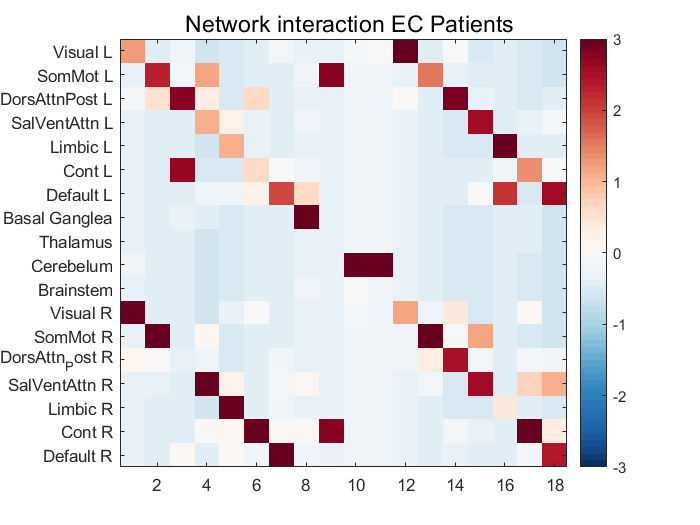

colors = flipud(colors); % puts red on top, blue at the bottom
colormap(colors);
colorbar();

XX

%%

